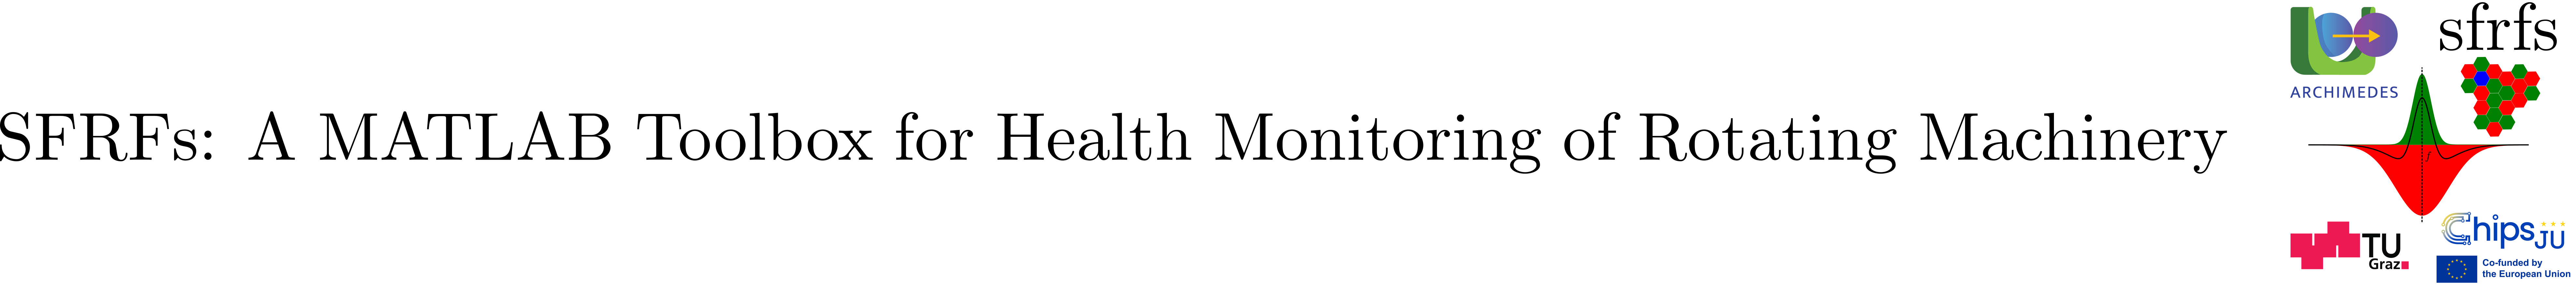

# CenterSurroundCompute

## Summary

Compute center, surround, and contrast responses from stacked spectra using receptive field gain functions (RFGFs).

## Description

`CenterSurroundCompute` evaluates receptive field responses by applying the center and surround spectral masks stored in a `ReceptiveFieldGainFunctions `instance to stacked spectra extracted from a run to failure member table.

Given a selected row in `rfgfs.gainFunctionsTable`, the class:

- Extracts the center and surround masks from the frequency bank mask record.

- Applies each mask to the stacked spectra.

- Computes center and surround responses via a configurable receptive field response function.

- Computes a contrast response via a contrast mapping.

### Dependent properties

The following dependent properties provide convenient access to derived objects and metadata used during center–surround evaluation.

### Constructor 

#### Construction syntax

`cs = CenterSurroundCompute( ...`

`    snapshotParameters = paramsSnapshot, ...`

`    rfgfs              = rfgfs);`

`with parameters given by:`

### Public methods

#### compute

**Syntax (by example):**

`[contrast, centerResponse, surroundResponse, ...`

`    centerMask, surroundMask, contrastMask] = ...`

                 `compute( ...`

`                memberTable    = T, ...`

`                spectralColumn = "FFT", ...`

`                row            = 1);`

**Outputs:**

### Notes

Contrast mappings in the current version are parameterized by an inhibition factor k, specified via the `inhibitionFactor` property obtained by the [`SFRFsParameters`](matlab:open('./SFRFsParameters.mlx')) class.

### See also

[`ReceptiveFieldGainFunctions`](matlab:open('./ReceptiveFieldGainFunctions.mlx')), [`ReceptiveFieldResponseFunctions`](matlab:open('./ReceptiveFieldResponseFunctions.mlx')), [`ContrastMappings`](matlab:open('./ContrastMappings.mlx')), [`FrequencyMask`](matlab:open('./FrequencyMask.mlx'))

## Example

% Snapshot descriptor (defines the frequency axis)
sp = ParametersSnapshot( ...
    samplingFrequency = 25600, ...
    duration          = 1.28, ...
    stride            = 60);

f = sp.getFrequencyDomain();

% Bearing geometry (example values)
bp = ParametersRollingBearings( ...
    numRollingElements = 8, ...
    ballDiameter       = 7.92, ...
    pitchDiameter      = 34.55, ...
    contactAngle       = 0);

% Shared SFRF params (Gaussian masks)
sharedParams = SFRFsParameters.buildSFRFsParameters( ...
    order            = 0, ...
    numSidebands     = 2, ...
    numHarmonics     = 10, ...
    centerMask       = GaussianMaskParameters( ...
        bandwidth = 4, ...
        sigmaRule = 1.0253), ...
    surroundMask     = GaussianMaskParameters( ...
        bandwidth = 12, ...
        sigmaRule = 0.8905), ...
    inhibitionFactor = 0.8647);

sfrfsParams = SFRFsParametersRollingBearings( ...
    SameForAllFaultTypes = sharedParams);

% Operating conditions (single condition for this example)
oc = OperatingConditions( ...
    [35], ... % speed
    [12]);    % load

% Diagnostic knowledge (bearing fault bands)
bfb = BearingFrequencyBands( ...
    bearingParams       = bp, ...
    sfrfsParams         = sfrfsParams, ...
    operatingConditions = oc);

bfb.computeBands();

% Receptive field gain functions (RFGFs)
rfgfs = ReceptiveFieldGainFunctions(bfb);
rfgfs.computeGainFunctions(f);

% Synthetic member table with stacked spectra
memberTable = buildSyntheticMemberTable(f, 50);


% Compute object creation
cs = CenterSurroundCompute( ...
    snapshotParameters = sp, ...
    rfgfs              = rfgfs);

% Select operating condition
sel = OperatingConditionSelection( ...
    speed = 35, ...
    load  = 12);

% Pick a fault type name defined by your rolling-bearing parameterization
faultType = SFRFsParametersRollingBearings.OUTER_RACE_FAULT_TYPE_NAME;

% Compute responses, contrast mask is DoG
[contrast, Rc, Rs, C, S, DoG] = cs.compute( ...
    memberTable    = memberTable, ...
    spectralColumn = "FFT", ...
    faultType      = faultType, ...
    selection      = sel);

## API documentation

### MATLAB help

help CenterSurroundCompute

 CenterSurroundCompute  Compute center/surround responses via RFGFs.
 
  Stores snapshot parameters and RFGFs handle, and computes receptive-field
  responses on stacked spectra extracted from a run-to-failure member 
  table.

    Documentation for CenterSurroundCompute



## Source code

The source of the class can be found in [CenterSurroundCompute](matlab:open('../../CenterSurroundCompute.m')).

## Test

The unit test for this class can be found in [TestCenterSurroundCompute](matlab:open('../../../tests/TestCenterSurroundCompute.m')).

% execute tests
res = runtests('Spectral Fault Receptive Fields/tests/TestCenterSurroundCompute');

Running TestCenterSurroundCompute
..
Done TestCenterSurroundCompute
__________



% display summary of tests
SFRFsTestUtil.printTestSummary(res,80);

Test Name                                                                        | Result
-----------------------------------------------------------------------------------------
TestCenterSurroundCompute/testComputeByRowProducesFiniteOutputs                  | Passed
TestCenterSurroundCompute/testComputeByFaultTypeSelectionIfAvailable             | Passed



## Auxiliary functions

### Synthetic member table construction

function memberTable = buildSyntheticMemberTable(f, nSnapshots)
% buildSyntheticMemberTable  Create a synthetic member table with stacked spectra
%
% memberTable = buildSyntheticMemberTable(f, nSnapshots)
%
% Inputs
%   f           Frequency vector
%   nSnapshots  Number of synthetic snapshots
%
% Output
%   memberTable Table with columns:
%               - SnapshotIndex
%               - FFT (cell array of spectral vectors)

nBins = numel(f);

FFT = cell(nSnapshots, 1);
for i = 1:nSnapshots
    x = abs(randn(nBins, 1));        % noise floor
    x = x + 0.05 * (f(:) / max(f));  % mild spectral slope
    FFT{i} = x;
end

memberTable = table((1:nSnapshots).', FFT, ...
    VariableNames = ["SnapshotIndex", "FFT"]);
end


## How to cite this work

Muñoz Gutiérrez, Stan, & Wotawa, Franz (2025). SFRFs: A MATLAB Toolbox for Health Monitoring of Rotating Machinery. Zenodo. DOI: [10.5281/zenodo.17631784](http://10.0.20.161/zenodo.17631784).

## References

- [1] Stan Muñoz Gutiérrez and Franz Wotawa. Optimized Spectral Fault Receptive Fields for Diagnosis-Informed Prognosis. In 36th International Conference on Principles of Diagnosis and Resilient Systems (DX 2025). Open Access Series in Informatics (OASIcs), Volume 136, pp. 9:1-9:20, Schloss Dagstuhl – Leibniz-Zentrum für Informatik (2025) [DOI:10.4230/OASIcs.DX.2025.9](https://doi.org/10.4230/OASIcs.DX.2025.9).